curdir = "C:\Users\mgorbun\Documents\MATLAB\TDS\paraphine";
files = struct2table(dir(curdir));
files = files.name(3:end,1);

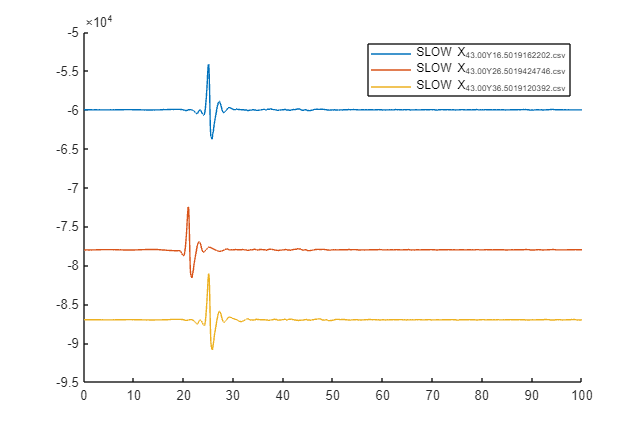

figure
hold on
outM = [];
for i = [20 26 29]
    a = readmatrix(fullfile(curdir, files(i)));
    b = TDS_FFT(a);
    % plot(b(:,1), b(:, 2))
    outM = [outM, b(:, 2)];
    plot(a(:,1), a(:,2)-3000*i, "DisplayName", files{i})
end
legend